% Define the system matrices A and B based on the given system
a = 5;
b = 3;
c = 1;
A = [a-b, 0.5-c; 0, 1];
B = [0; 1];

% Define the selected sampling interval(tau = h)
h = 0.05;
tau = linspace(0, 1.5*h, 15);


x = sdpvar(4,4); % x = inv(P)
y = sdpvar(1,4); % y = K*inv(P), dim(K) = dim(y)

con1 =[];
con2 = [x >= eye(4,4)^(-10)];
for i =1:length(tau)
%when 0=<tau<h
if tau(i) < h
        %new augumented system to match dimension
        Fx = expm(A*h);
        Fu = (expm(A*h) - expm(A*(h-tau(i))))/A * B;
        G1 = (expm(A*(h-tau(i))) - eye(size(A)))/A * B;
        Fe = [Fx, Fu, zeros(2,1); zeros(1,4); zeros(1,2), 1, 0];
        Ge = [G1; 1; 0];

%when h<tau<=1.5h
else 
        Fxh = expm(A*h);
        Fuh = (expm(A*h) - expm(A*(2*h-tau(i))))/A * B;
        Gh = (expm(A*(2*h-tau(i))) - eye(size(A)))/A * B;
        Fe = [Fxh, Fuh, Gh; zeros(size(Fxh)),[0;1],zeros(2,1)]; 
        Ge = [zeros(size(Fxh(:,1))); 1; 0];
end
% Check stability using LMIs(for discrete-time case)
con1 = [con1; [x, Fe*x-Ge*y; x*(Fe)'-(Ge*y)', x] >= eye(8,8)^(-10)];
end
cons = [con1, con2];
options = sdpsettings('solver', 'sedumi');
sol = optimize(cons, [], options);

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 14, order n = 125, dim = 977, blocks = 17
nnz(A) = 842 + 0, nnz(ADA) = 196, nnz(L) = 105
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.69E+01 0.000
  1 :   0.00E+00 1.01E+01 0.000 0.6000 0.9000 0.9000  -4.54  1  1  3.9E+02
  2 :   0.00E+00 3.51E+00 0.000 0.3461 0.9000 0.9000  -7.22  1  1  3.6E+01
  3 :   0.00E+00 8.11E-01 0.000 0.2311 0.9000 0.9000  -1.23  1  1  4.8E+01
  4 :   0.00E+00 1.91E-01 0.000 0.2357 0.9000 0.9000  -1.44  1  1  6.1E+01
  5 :   0.00E+00 5.10E-02 0.000 0.2667 0.9000 0.9000  -1.05  1  1  5.2E+01
  6 :   0.00E+00 1.01E-02 0.000 0.1987 0.9000 0.9000  -0.65  1  1  4.2E+01
  7 :   0.00E+00 2.65E-03 0.000 0.2618 0.9000 0.9000  -0.84  1  1  3.7E+01
  8 :   0.00E+00 9.56E-04 0.000 0.3603 0.9000 0.9000  -0.47  1  1  2.5E+01
  9 :   0.00E+00 2.34E-04 0.000 0.2446 0.9000 0.9000   0.24  1  1  8.2E+00
 10 :   0.

disp(sol.info);

Successfully solved (SeDuMi-1.3)



if sol.problem == 0
    disp('The sampled-data controller is stable.');
    X = value(x)
    Y = value(y)
    K = Y * inv(X)
else
    disp('The sampled-data controller is unstable.');
end

The sampled-data controller is stable.


X = 1.0e+04 *

    0.0357    0.1533   -0.1150   -0.1074
    0.1533    0.7556   -0.9113   -0.8706
   -0.1150   -0.9113    3.1393    2.0468
   -0.1074   -0.8706    2.0468    4.3787


Y = 1.0e+04 *

    0.1269    0.9512   -2.0194   -1.9590


K =   -17.5941    5.0767    0.1451    0.0626


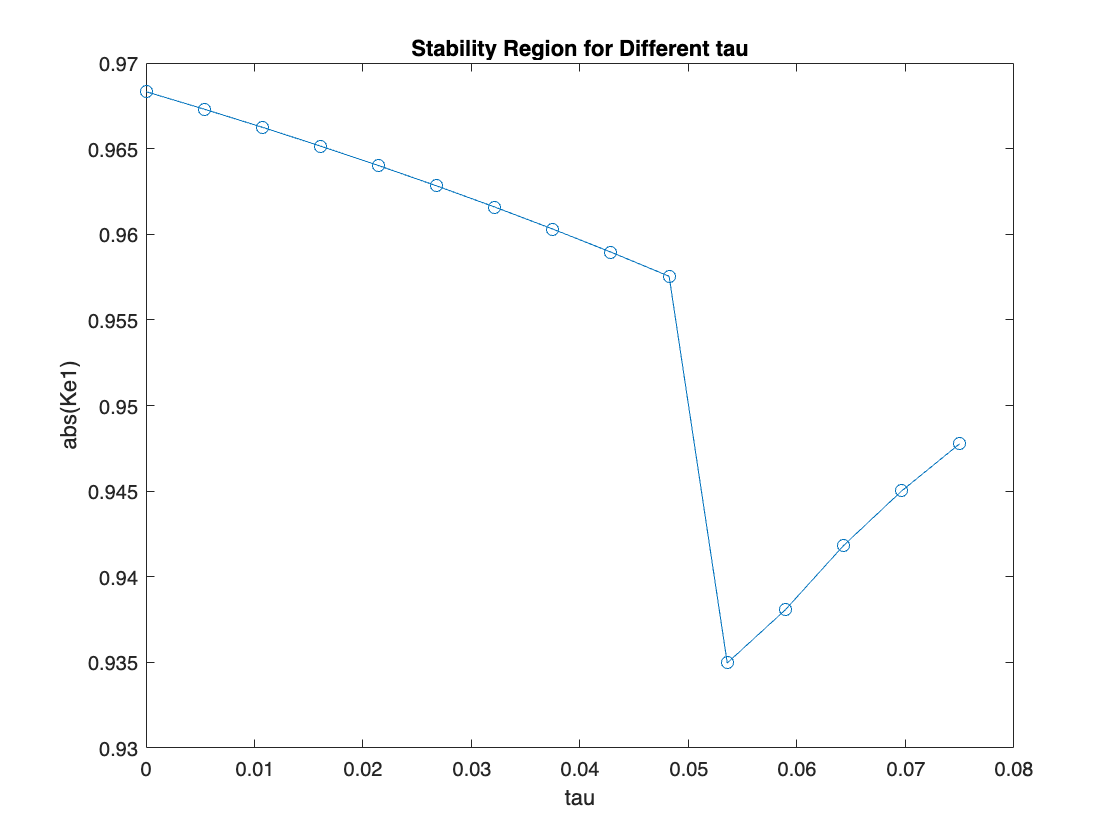

Ke1 = Fe - Ge*K;
eig(Ke1); %stable

% Plot
result = zeros(size(tau));
for i = 1:length(tau)
    % When 0 <= tau < h
    if tau(i) < h
        Fx = expm(A*h);
        Fu = (expm(A*h) - expm(A*(h-tau(i))))/A * B;
        G1 = (expm(A*(h-tau(i))) - eye(size(A)))/A * B;
        Fe = [Fx, Fu, zeros(2,1); zeros(1,4); zeros(1,2), 1, 0];
        Ge = [G1; 1; 0];
    % When h < tau <= 1.5h
    elseif tau(i) <= 1.5*h
        Fxh = expm(A*h);
        Fuh = (expm(A*h) - expm(A*(2*h-tau(i))))/A * B;
        Gh = (expm(A*(2*h-tau(i))) - eye(size(A)))/A * B;
        Fe = [Fxh, Fuh, Gh; zeros(size(Fxh)),[0;1],zeros(2,1)]; 
        Ge = [zeros(size(Fxh(:,1))); 1; 0];
    end
    
    Ke1 = Fe - Ge*K;
    result(i) = max(abs(eig(Ke1))) ;
    %result(i) = max(abs(eig(Ke1))) < 1; %it should be all '1'
end

% Plotting
plot(tau, result, 'o-');
xlabel('tau');
ylabel('abs(Ke1)');
title('Stability Region for Different tau');